clc; clear;
dsFolder = "p_dataset_26";
subFolder = ["0", "4", "7", "8", "A", "D", "H"];
categories = ["0", "4", "7", "8", "A", "D", "H"];

allData = table('Size', [0, 2], 'VariableTypes', {'cell', 'cell'}, 'VariableNames', {'Image', 'Label'});

for i = 1:length(subFolder)
    folderPath = fullfile(dsFolder, subFolder(i));
    pngFiles = dir(fullfile(folderPath, "*.png"));

    for j = 1:length(pngFiles)
        pngFilePath = fullfile(folderPath, pngFiles(j).name);
        image = imread(pngFilePath);
        allData = [allData; {image, categories(i)}];
    end
end

% define images & labels
numImages = size(allData, 1);
imageSize = size(allData.Image{1});
images = zeros(imageSize(1), imageSize(2), 1, numImages);

for i = 1:numImages
    images(:, :, 1, i) = allData.Image{i};
end

labels = categorical(allData.Label);

% split data into train and test set
cv = cvpartition(labels, 'HoldOut', 0.25);
trainIdx = training(cv);
testIdx = test(cv);
trainImages = images(:, :, :, trainIdx);
trainLabels = labels(trainIdx);
testImages = images(:, :, :, testIdx);
testLabels = labels(testIdx);

% Define the layers of the CNN
layers = [
    imageInputLayer([imageSize 1])

    convolution2dLayer(3, 8, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    fullyConnectedLayer(numel(categories))
    softmaxLayer
    classificationLayer
    ];

% Training options
options = trainingOptions( ...
    'sgdm', ... % Stochastic Gradient Descent with Momentum
    'InitialLearnRate', 0.01, ...
    'MaxEpochs', 10, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {testImages, testLabels}, ...
    'ValidationFrequency', 30, ...
    'Verbose', true, ...
    'Plots', 'training-progress' ...
    );

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |       18.75% |       20.05% |       2.4268 |       5.9316 |          0.0100 |
|       3 |          30 |       00:00:19 |       90.62% |       90.77% |       0.3309 |       0.2974 |          0.0100 |
|       5 |          50 |       00:00:28 |       93.75% |              |       0.1977 |              |          0.0100 |
|       6 |          60 |       00:00:34 |       95.31% |       94.59% |       0.1674 |   

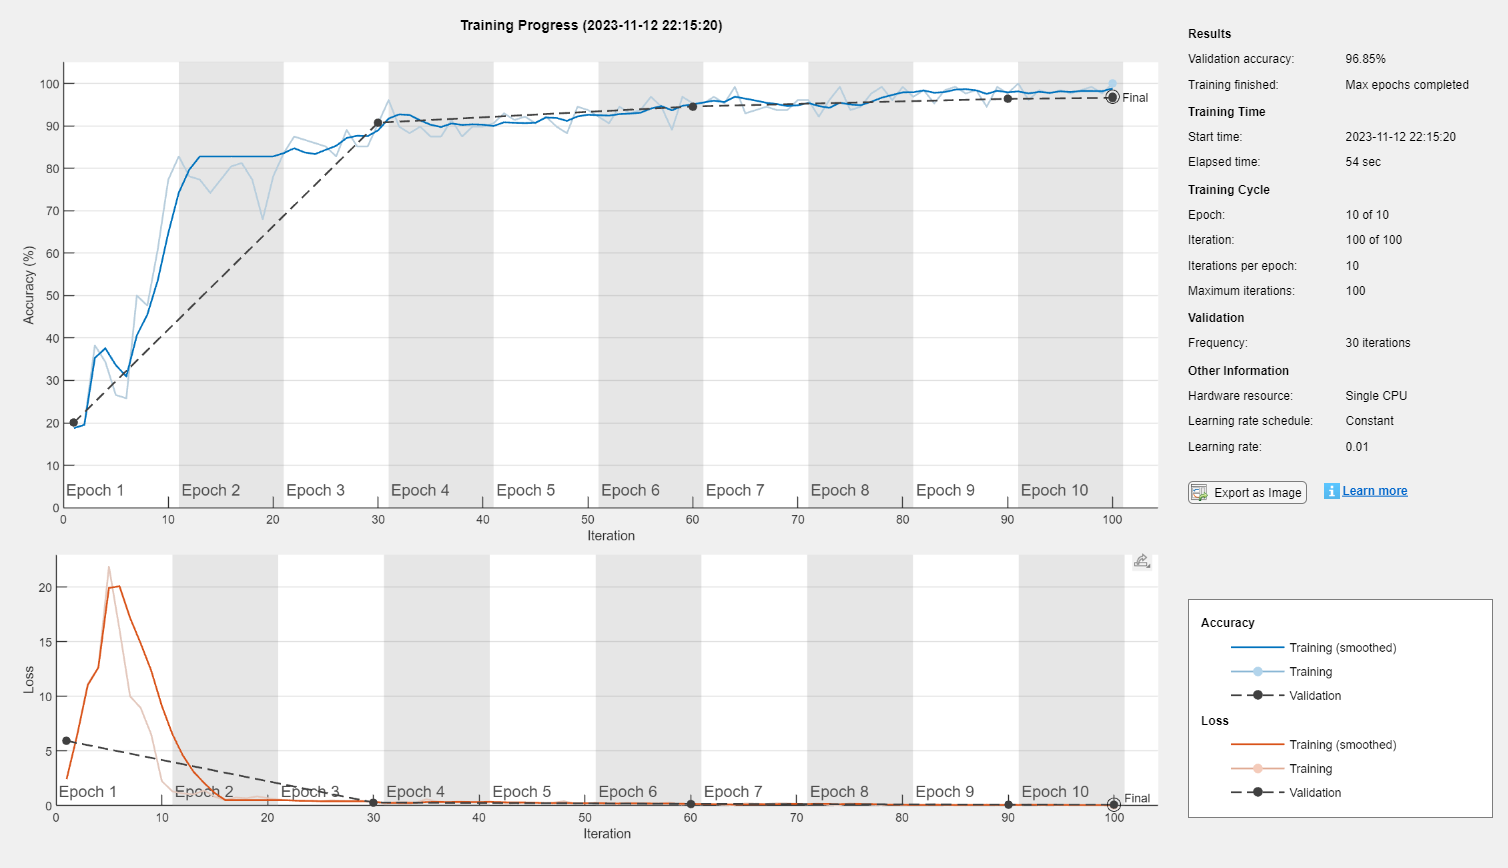

% Train the CNN
net = trainNetwork(trainImages, trainLabels, layers, options);

% Classify Test Images
predictedLabels = classify(net, testImages);

% Calculate the Accuracy
accuracy = sum(predictedLabels == testLabels) / numel(testLabels);
fprintf('Test Accuracy: %.2f%%\n', accuracy * 100);

Test Accuracy: 96.85%
